# PID Aircraft Pitch Control

The goal of this example is to design a Proportional-Integral-derivative (PID) for the case of a linearized, decoupled model of aircraft pitch dynamics. This example is inspired from: http://ctms.engin.umich.edu/CTMS/index.php?example=AircraftPitch&section=ControlPID

## System Modeling

The aircraft pitch model takes the following form in transfer function representation:


$$P(s)=\frac{\Theta(s)}{\Delta(s)} = \frac{1.151s + 0.1774}{s^3 + 0.739s^2 + 0.921s}$$


where the input is the elevator $\delta$ and the output is the aircraft pitch angle $\theta$. 

s = tf('s');
P_pitch = (1.151*s+0.1774)/(s^3+0.739*s^2+0.921*s);

## Desired Control Performance Criteria

For a step reference of 0.2 radians, the design criteria are the following.

- Overshoot less than 10%

- Rise time less than 2 seconds

- Settling time less than 10 seconds

- Steady-state error less than 2%

## PID Control structure

The PID Control structure takes the following form in the Laplace domain:


$$C(s) = K_p + \frac{K_i}{s}+K_d s = \frac{K_d s^2 + K_p s + K_i }{s}$$


## PID Control Synthesis

PID control tuning is a topic handled both using empirical methods as well as optimized tools. MATLAB provides the function sisotool which simplfies the process of designing efficient PID Controllers that satisfy desirable performance criteria when this is possible. To run this command considering a full PID structure (with all three gains) we use the following:

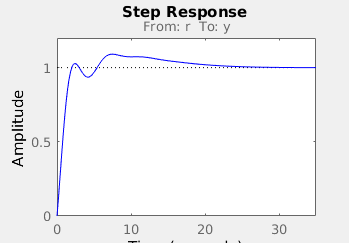

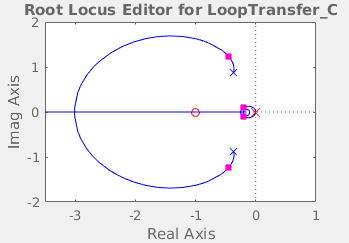

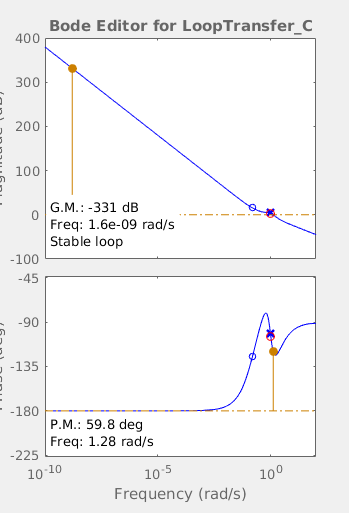

K_p_dummy = 1; K_i_dummy = .5; K_d_dummy = .5;
pid_init = (K_d_dummy * s^2 + K_p_dummy * s + K_i_dummy)/s;
prefilt_init = 1;
sisotool(P_pitch,pid_init,[],prefilt_init)

Once this command is executed, a set of plots are depicted based on the input system (P_pitch) and initial controller assumptions (not tuned). To properlly tune the controller, we may choose "Tuning Methods ->  Optimization Based Tuning". In the "Design Requirements" panel we add all the abovementioned desired control performance criteria using the "Add new design requirement" button (note we set r2y design requirements). We click OK and then "Start Optimization" once we have entered the "Compensators" panel and clicked them all. 

## PID Control Synthesis

Evaluation of the controller can take place once it is designed. At this moment you should have designed your own controller. For the rest of this example we load a saved controller which was designed as described aboce.

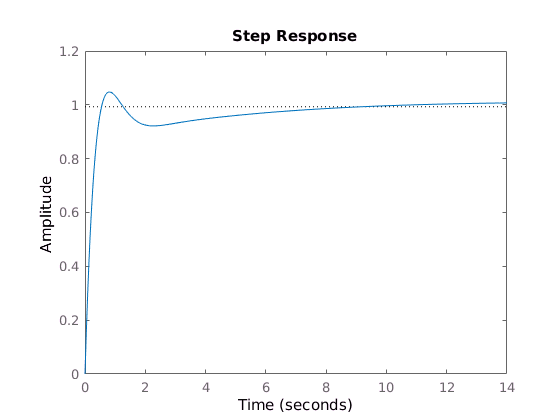

load('derived_pid.mat');
prefilt_tf = F;
pid_tf = C;
sys_cl = prefilt_tf * feedback(pid_tf*P_pitch,1);
step(sys_cl)